%% ANÁLISIS DEL ATRACTOR DE LÜ - CORRECCIÓN CASOS DEGENERADOS
% Sistema:
% x' = α(y - x)
% y' = -xz + δy  
% z' = xy - βz

clear; clc; close all;

%% PARÁMETROS Y CONFIGURACIÓN
alpha = 36;
beta = 3;
delta = 20;

% Condiciones iniciales
initial_conditions = [0.1, 0.3, -0.6];

%% 8.1 - PUNTOS CRÍTICOS EN FUNCIÓN DE PARÁMETROS
fprintf('=== 8.1 - PUNTOS CRÍTICOS ===\n');

=== 8.1 - PUNTOS CRÍTICOS ===



% Definir sistema simbólico
syms x y z a b d
f1 = a*(y - x);
f2 = -x*z + d*y;
f3 = x*y - b*z;

% Resolver sistema para puntos críticos
[x_sol, y_sol, z_sol] = solve(f1 == 0, f2 == 0, f3 == 0, x, y, z);

fprintf('Puntos críticos encontrados:\n');

Puntos críticos encontrados:


for i = 1:length(x_sol)
    fprintf('P%d = (%s, %s, %s)\n', i, char(x_sol(i)), char(y_sol(i)), char(z_sol(i)));
end

P1 = (0, 0, 0)
P2 = (-(b*d)^(1/2), -(b*d)^(1/2), d)
P3 = ((b*d)^(1/2), (b*d)^(1/2), d)



% Evaluar con parámetros específicos
x_crit = subs(x_sol, [a, b, d], [alpha, beta, delta]);
y_crit = subs(y_sol, [a, b, d], [alpha, beta, delta]);
z_crit = subs(z_sol, [a, b, d], [alpha, beta, delta]);

fprintf('\nPuntos críticos con α=%g, β=%g, δ=%g:\n', alpha, beta, delta);


Puntos críticos con α=36, β=3, δ=20:


for i = 1:length(x_crit)
    fprintf('P%d = (%.4f, %.4f, %.4f)\n', i, double(x_crit(i)), double(y_crit(i)), double(z_crit(i)));
end

P1 = (0.0000, 0.0000, 0.0000)
P2 = (-7.7460, -7.7460, 20.0000)
P3 = (7.7460, 7.7460, 20.0000)



%% 8.2 - ESTABILIDAD DEL ORIGEN (0,0,0) - CASOS COMPLETOS CORREGIDOS
fprintf('\n=== 8.2 - ESTABILIDAD DEL ORIGEN - ANÁLISIS COMPLETO ===\n');


=== 8.2 - ESTABILIDAD DEL ORIGEN - ANÁLISIS COMPLETO ===



% Matriz jacobiana
J = jacobian([f1; f2; f3], [x, y, z]);

% ================================================
% CASO 1: Todos los parámetros distintos de 0
% ================================================
fprintf('\n--- CASO 1: α≠0, β≠0, δ≠0 ---\n');


--- CASO 1: α≠0, β≠0, δ≠0 ---



J_origin_1 = subs(J, [x, y, z], [0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_1);

$$\left(\begin{array}{ccc} -a & a & 0\\ 0 & d & 0\\ 0 & 0 & -b \end{array}\right)$$


% Evaluar con parámetros específicos
J_origin_1_num = double(subs(J_origin_1, [a, b, d], [alpha, beta, delta]));
eigenvals_1_num = eig(J_origin_1_num);

fprintf('Autovalores numéricos con α=%g, β=%g, δ=%g:\n', alpha, beta, delta);

Autovalores numéricos con α=36, β=3, δ=20:


for i = 1:length(eigenvals_1_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_1_num(i)), imag(eigenvals_1_num(i)));
end

λ1 = -36.0000 +0.0000i
λ2 = 20.0000 +0.0000i
λ3 = -3.0000 +0.0000i



% Determinar estabilidad
if all(real(eigenvals_1_num) < 0)
    fprintf('ESTABLE: todos los autovalores tienen parte real negativa\n');
elseif all(real(eigenvals_1_num) <= 0)
    fprintf('MARGINALMENTE ESTABLE\n');
else
    fprintf('INESTABLE: al menos un autovalor tiene parte real positiva\n');
end

INESTABLE: al menos un autovalor tiene parte real positiva



% ================================================
% CASO 2: Todos los parámetros iguales a 0 - CORREGIDO
% ================================================
fprintf('\n--- CASO 2: α=0, β=0, δ=0 ---\n');


--- CASO 2: α=0, β=0, δ=0 ---



J_origin_2 = subs(J, [x, y, z, a, b, d], [0, 0, 0, 0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_2);

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


det_J_2 = det(J_origin_2);
fprintf('Determinante: %s\n', char(det_J_2));

Determinante: 0



eigenvals_2 = eig(J_origin_2);
fprintf('Autovalores:\n');

Autovalores:


for i = 1:length(eigenvals_2)
    fprintf('λ%d = %s\n', i, char(eigenvals_2(i)));
end

λ1 = 0
λ2 = 0
λ3 = 0



fprintf('ANÁLISIS: Todos los autovalores son cero\n');

ANÁLISIS: Todos los autovalores son cero


fprintf('SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA\n');

SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA



% ================================================
% CASO 3: α=δ=0 y β≠0 - CORREGIDO
% ================================================
fprintf('\n--- CASO 3: α=0, δ=0, β≠0 ---\n');


--- CASO 3: α=0, δ=0, β≠0 ---



% Sustituir completamente en la matriz jacobiana
J_origin_3 = subs(J, [x, y, z, a, d], [0, 0, 0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_3);

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -b \end{array}\right)$$


det_J_3 = det(J_origin_3);
fprintf('Determinante: %s\n', char(det_J_3));

Determinante: 0



eigenvals_3 = eig(J_origin_3);
fprintf('Autovalores:\n');

Autovalores:


for i = 1:length(eigenvals_3)
    fprintf('λ%d = %s\n', i, char(simplify(eigenvals_3(i))));
end

λ1 = 0
λ2 = 0
λ3 = -b



% Evaluar numéricamente con β específico
beta_test = 3;
J_origin_3_num = double(subs(J_origin_3, b, beta_test));
eigenvals_3_num = eig(J_origin_3_num);

fprintf('\nAutovalores numéricos con β=%g:\n', beta_test);


Autovalores numéricos con β=3:


for i = 1:length(eigenvals_3_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_3_num(i)), imag(eigenvals_3_num(i)));
end

λ1 = -3.0000 +0.0000i
λ2 = 0.0000 +0.0000i
λ3 = 0.0000 +0.0000i



fprintf('ANÁLISIS: Autovalor real negativo (-β) y autovalor cero doble\n');

ANÁLISIS: Autovalor real negativo (-β) y autovalor cero doble


fprintf('SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA\n');

SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA



% ================================================
% CASO 4: α=0 y δ≠0 (β arbitrario) - CORREGIDO
% ================================================
fprintf('\n--- CASO 4: α=0, δ≠0 (β arbitrario) ---\n');


--- CASO 4: α=0, δ≠0 (β arbitrario) ---



J_origin_4 = subs(J, [x, y, z, a], [0, 0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_4);

$$\left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & d & 0\\ 0 & 0 & -b \end{array}\right)$$


% Evaluar con parámetros específicos
delta_test = 20;
beta_test = 3;
J_origin_4_num = double(subs(J_origin_4, [b, d], [beta_test, delta_test]));
eigenvals_4_num = eig(J_origin_4_num);

fprintf('Autovalores numéricos con δ=%g, β=%g:\n', delta_test, beta_test);

Autovalores numéricos con δ=20, β=3:


for i = 1:length(eigenvals_4_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_4_num(i)), imag(eigenvals_4_num(i)));
end

λ1 = -3.0000 +0.0000i
λ2 = 0.0000 +0.0000i
λ3 = 20.0000 +0.0000i



% Determinar estabilidad
if all(real(eigenvals_4_num) < 0)
    fprintf('ESTABLE: todos los autovalores tienen parte real negativa\n');
elseif all(real(eigenvals_4_num) <= 0)
    fprintf('MARGINALMENTE ESTABLE\n');
else
    fprintf('INESTABLE: al menos un autovalor tiene parte real positiva\n');
end

INESTABLE: al menos un autovalor tiene parte real positiva



% ================================================
% CASO 5: α≠0 y β=0 (δ arbitrario) - CORREGIDO
% ================================================
fprintf('\n--- CASO 5: α≠0, β=0 (δ arbitrario) ---\n');


--- CASO 5: α≠0, β=0 (δ arbitrario) ---



J_origin_5 = subs(J, [x, y, z, b], [0, 0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_5);

$$\left(\begin{array}{ccc} -a & a & 0\\ 0 & d & 0\\ 0 & 0 & 0 \end{array}\right)$$


% Evaluar con parámetros específicos
alpha_test = 36;
delta_test = 20;
J_origin_5_num = double(subs(J_origin_5, [a, d], [alpha_test, delta_test]));
eigenvals_5_num = eig(J_origin_5_num);

fprintf('Autovalores numéricos con α=%g, δ=%g:\n', alpha_test, delta_test);

Autovalores numéricos con α=36, δ=20:


for i = 1:length(eigenvals_5_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_5_num(i)), imag(eigenvals_5_num(i)));
end

λ1 = -36.0000 +0.0000i
λ2 = 20.0000 +0.0000i
λ3 = 0.0000 +0.0000i



fprintf('ANÁLISIS: Determinante cero → sistema singular\n');

ANÁLISIS: Determinante cero → sistema singular


fprintf('SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA\n');

SISTEMA DEGENERADO - ESTABILIDAD INDETERMINADA



% ================================================
% CASO 6: α≠0 y β≠0 (δ arbitrario) - CORREGIDO
% ================================================
fprintf('\n--- CASO 6: α≠0, β≠0 (δ arbitrario) ---\n');


--- CASO 6: α≠0, β≠0 (δ arbitrario) ---



J_origin_6 = subs(J, [x, y, z], [0, 0, 0]);
fprintf('Matriz jacobiana en (0,0,0):\n');

Matriz jacobiana en (0,0,0):


disp(J_origin_6);

$$\left(\begin{array}{ccc} -a & a & 0\\ 0 & d & 0\\ 0 & 0 & -b \end{array}\right)$$


% Evaluar con δ específico
delta_test = 20;
J_origin_6_num = double(subs(J_origin_6, [a, b, d], [alpha, beta, delta_test]));
eigenvals_6_num = eig(J_origin_6_num);

fprintf('Autovalores numéricos con α=%g, β=%g, δ=%g:\n', alpha, beta, delta_test);

Autovalores numéricos con α=36, β=3, δ=20:


for i = 1:length(eigenvals_6_num)
    fprintf('λ%d = %.4f %+.4fi\n', i, real(eigenvals_6_num(i)), imag(eigenvals_6_num(i)));
end

λ1 = -36.0000 +0.0000i
λ2 = 20.0000 +0.0000i
λ3 = -3.0000 +0.0000i



% Determinar estabilidad
if all(real(eigenvals_6_num) < 0)
    fprintf('ESTABLE: todos los autovalores tienen parte real negativa\n');
elseif all(real(eigenvals_6_num) <= 0)
    fprintf('MARGINALMENTE ESTABLE\n');
else
    fprintf('INESTABLE: al menos un autovalor tiene parte real positiva\n');
end

INESTABLE: al menos un autovalor tiene parte real positiva



%% GRÁFICAS DE TRAYECTORIAS PARA CASOS DEGENERADOS
fprintf('\n=== GRÁFICAS DE TRAYECTORIAS PARA CASOS DEGENERADOS ===\n');


=== GRÁFICAS DE TRAYECTORIAS PARA CASOS DEGENERADOS ===



% Función para resolver y graficar el sistema
function plot_trajectories(alpha_val, beta_val, delta_val, case_name, t_span)
    % Definir el sistema de ecuaciones
    lorenz_system = @(t, X) [
        alpha_val * (X(2) - X(1));
        -X(1)*X(3) + delta_val * X(2);
        X(1)*X(2) - beta_val * X(3)
    ];
    
    % Condiciones iniciales múltiples para ver comportamiento
    initial_conditions_set = [
        0.1, 0.3, -0.6;
        1.0, 0.5, 0.2;
        -0.5, -0.8, 0.4;
        0.01, 0.01, 0.01
    ];
    
    figure('Position', [100, 100, 1200, 900]);
    
    % Colores para diferentes condiciones iniciales
    colors = ['r', 'g', 'b', 'm'];
    
    for i = 1:size(initial_conditions_set, 1)
        try
            % Resolver el sistema
            [t, X] = ode45(lorenz_system, t_span, initial_conditions_set(i, :));
            
            % Gráfica 3D
            subplot(2, 2, 1);
            plot3(X(:,1), X(:,2), X(:,3), colors(i), 'LineWidth', 1.5);
            hold on;
            plot3(X(1,1), X(1,2), X(1,3), [colors(i) 'o'], 'MarkerSize', 6, 'MarkerFaceColor', colors(i));
            
            % Gráficas de componentes vs tiempo
            subplot(2, 2, 2);
            plot(t, X(:,1), colors(i), 'LineWidth', 1.5); hold on;
            
            subplot(2, 2, 3);
            plot(t, X(:,2), colors(i), 'LineWidth', 1.5); hold on;
            
            subplot(2, 2, 4);
            plot(t, X(:,3), colors(i), 'LineWidth', 1.5); hold on;
        catch ME
            fprintf('Advertencia: No se pudo resolver para condición inicial %d\n', i);
        end
    end
    
    % Configurar gráfica 3D
    subplot(2, 2, 1);
    grid on;
    xlabel('x'); ylabel('y'); zlabel('z');
    title(sprintf('%s - Trayectorias 3D\nα=%g, β=%g, δ=%g', case_name, alpha_val, beta_val, delta_val));
    legend('Tray. 1', 'Inic. 1', 'Tray. 2', 'Inic. 2', 'Tray. 3', 'Inic. 3', 'Tray. 4', 'Inic. 4', 'Location', 'best');
    
    % Configurar gráficas de componentes
    subplot(2, 2, 2);
    grid on; xlabel('Tiempo'); ylabel('x(t)');
    title('Componente x vs tiempo');
    legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');
    
    subplot(2, 2, 3);
    grid on; xlabel('Tiempo'); ylabel('y(t)');
    title('Componente y vs tiempo');
    legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');
    
    subplot(2, 2, 4);
    grid on; xlabel('Tiempo'); ylabel('z(t)');
    title('Componente z vs tiempo');
    legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');
    
    sgtitle(sprintf('Análisis de Trayectorias - %s', case_name));
end

% Gráficas para casos degenerados
fprintf('\nGraficando CASO 2 (α=β=δ=0)...\n');


Graficando CASO 2 (α=β=δ=0)...


plot_trajectories(0, 0, 0, 'Caso 2: α=β=δ=0 (Completamente Degenerado)', [0, 10]);

fprintf('Graficando CASO 3 (α=δ=0, β=3)...\n');

Graficando CASO 3 (α=δ=0, β=3)...


plot_trajectories(0, 3, 0, 'Caso 3: α=δ=0, β=3 (Degenerado)', [0, 20]);

fprintf('Graficando CASO 5 (α=36, β=0, δ=20)...\n');

Graficando CASO 5 (α=36, β=0, δ=20)...


plot_trajectories(36, 0, 20, 'Caso 5: α=36, β=0, δ=20 (Singular)', [0, 5]);

%% ANÁLISIS DETALLADO DE COMPORTAMIENTO DEGENERADO
fprintf('\n=== ANÁLISIS DETALLADO DE COMPORTAMIENTO DEGENERADO ===\n');


=== ANÁLISIS DETALLADO DE COMPORTAMIENTO DEGENERADO ===



% Análisis del Caso 2: α=β=δ=0
fprintf('\n1. CASO 2 (α=β=δ=0):\n');


1. CASO 2 (α=β=δ=0):


fprintf('   Sistema: x''=0, y''=-xz, z''=xy\n');

   Sistema: x'=0, y'=-xz, z'=xy


fprintf('   - x(t) = x₀ (constante)\n');

   - x(t) = x₀ (constante)


fprintf('   - Si x₀ = 0: y''=0, z''=0 → todo punto es equilibrio\n');

   - Si x₀ = 0: y'=0, z'=0 → todo punto es equilibrio


fprintf('   - Si x₀ ≠ 0: Sistema se reduce a y''=-x₀z, z''=x₀y\n');

   - Si x₀ ≠ 0: Sistema se reduce a y'=-x₀z, z'=x₀y


fprintf('   - Solución: y(t) = A*cos(x₀*t) + B*sin(x₀*t)\n');

   - Solución: y(t) = A*cos(x₀*t) + B*sin(x₀*t)


fprintf('   - Comportamiento oscilatorio armónico\n');

   - Comportamiento oscilatorio armónico



% Análisis del Caso 3: α=δ=0, β≠0
fprintf('\n2. CASO 3 (α=δ=0, β≠0):\n');


2. CASO 3 (α=δ=0, β≠0):


fprintf('   Sistema: x''=0, y''=-xz, z''=xy - βz\n');

   Sistema: x'=0, y'=-xz, z'=xy - βz


fprintf('   - x(t) = x₀ (constante)\n');

   - x(t) = x₀ (constante)


fprintf('   - Si x₀ = 0: y''=0, z''=-βz → z decae exponencialmente\n');

   - Si x₀ = 0: y'=0, z'=-βz → z decae exponencialmente


fprintf('   - Si x₀ ≠ 0: Sistema lineal en (y,z) con matriz:\n');

   - Si x₀ ≠ 0: Sistema lineal en (y,z) con matriz:


fprintf('        [0   -x₀]\n');

        [0   -x₀]


fprintf('        [x₀  -β]\n');

        [x₀  -β]



% Análisis del Caso 5: α≠0, β=0, δ≠0
fprintf('\n3. CASO 5 (α≠0, β=0, δ≠0):\n');


3. CASO 5 (α≠0, β=0, δ≠0):


fprintf('   Sistema: x''=α(y-x), y''=-xz + δy, z''=xy\n');

   Sistema: x'=α(y-x), y'=-xz + δy, z'=xy


fprintf('   - Sin término de disipación en z (β=0)\n');

   - Sin término de disipación en z (β=0)


fprintf('   - z puede crecer sin límite si xy > 0\n');

   - z puede crecer sin límite si xy > 0


fprintf('   - Comportamiento típicamente explosivo\n');

   - Comportamiento típicamente explosivo



%% RESUMEN FINAL
fprintf('\n=== RESUMEN FINAL CORREGIDO ===\n');


=== RESUMEN FINAL CORREGIDO ===


fprintf('Caso 1 (α≠0, β≠0, δ≠0): INESTABLE (atractor caótico)\n');

Caso 1 (α≠0, β≠0, δ≠0): INESTABLE (atractor caótico)


fprintf('Caso 2 (α=β=δ=0): SISTEMA DEGENERADO - Oscilaciones armónicas\n');

Caso 2 (α=β=δ=0): SISTEMA DEGENERADO - Oscilaciones armónicas


fprintf('Caso 3 (α=δ=0, β≠0): SISTEMA DEGENERADO - Comportamiento dependiente de x₀\n');

Caso 3 (α=δ=0, β≠0): SISTEMA DEGENERADO - Comportamiento dependiente de x₀


fprintf('Caso 4 (α=0, δ≠0): INESTABLE para δ>hu870\n');

Caso 4 (α=0, δ≠0): INESTABLE para δ>hu870


fprintf('Caso 5 (α≠0, β=0): SISTEMA SINGULAR - Crecimiento potencial\n');

Caso 5 (α≠0, β=0): SISTEMA SINGULAR - Crecimiento potencial


fprintf('Caso 6 (α≠0, β≠0): INESTABLE para parámetros típicos\n');

Caso 6 (α≠0, β≠0): INESTABLE para parámetros típicos



fprintf('\n=== CONCLUSIONES ===\n');


=== CONCLUSIONES ===


fprintf('1. El análisis lineal falla para sistemas degenerados\n');

1. El análisis lineal falla para sistemas degenerados


fprintf('2. La dinámica real se revela mediante simulación numérica\n');

2. La dinámica real se revela mediante simulación numérica


fprintf('3. Los casos degenerados muestran alta sensibilidad a condiciones iniciales\n');

3. Los casos degenerados muestran alta sensibilidad a condiciones iniciales


fprintf('4. El comportamiento puede ser cualitativamente diferente al predicho por linealización\n');

4. El comportamiento puede ser cualitativamente diferente al predicho por linealización





%% GRÁFICO CONCRETO PARA α=β=δ=0 CON CONDICIÓN INICIAL (1,1,1) - CON COLORBAR TEMPORAL
clear; clc; close all;

fprintf('=== ANÁLISIS CONCRETO: α=β=δ=0, Condición inicial (1,1,1) ===\n');

=== ANÁLISIS CONCRETO: α=β=δ=0, Condición inicial (1,1,1) ===


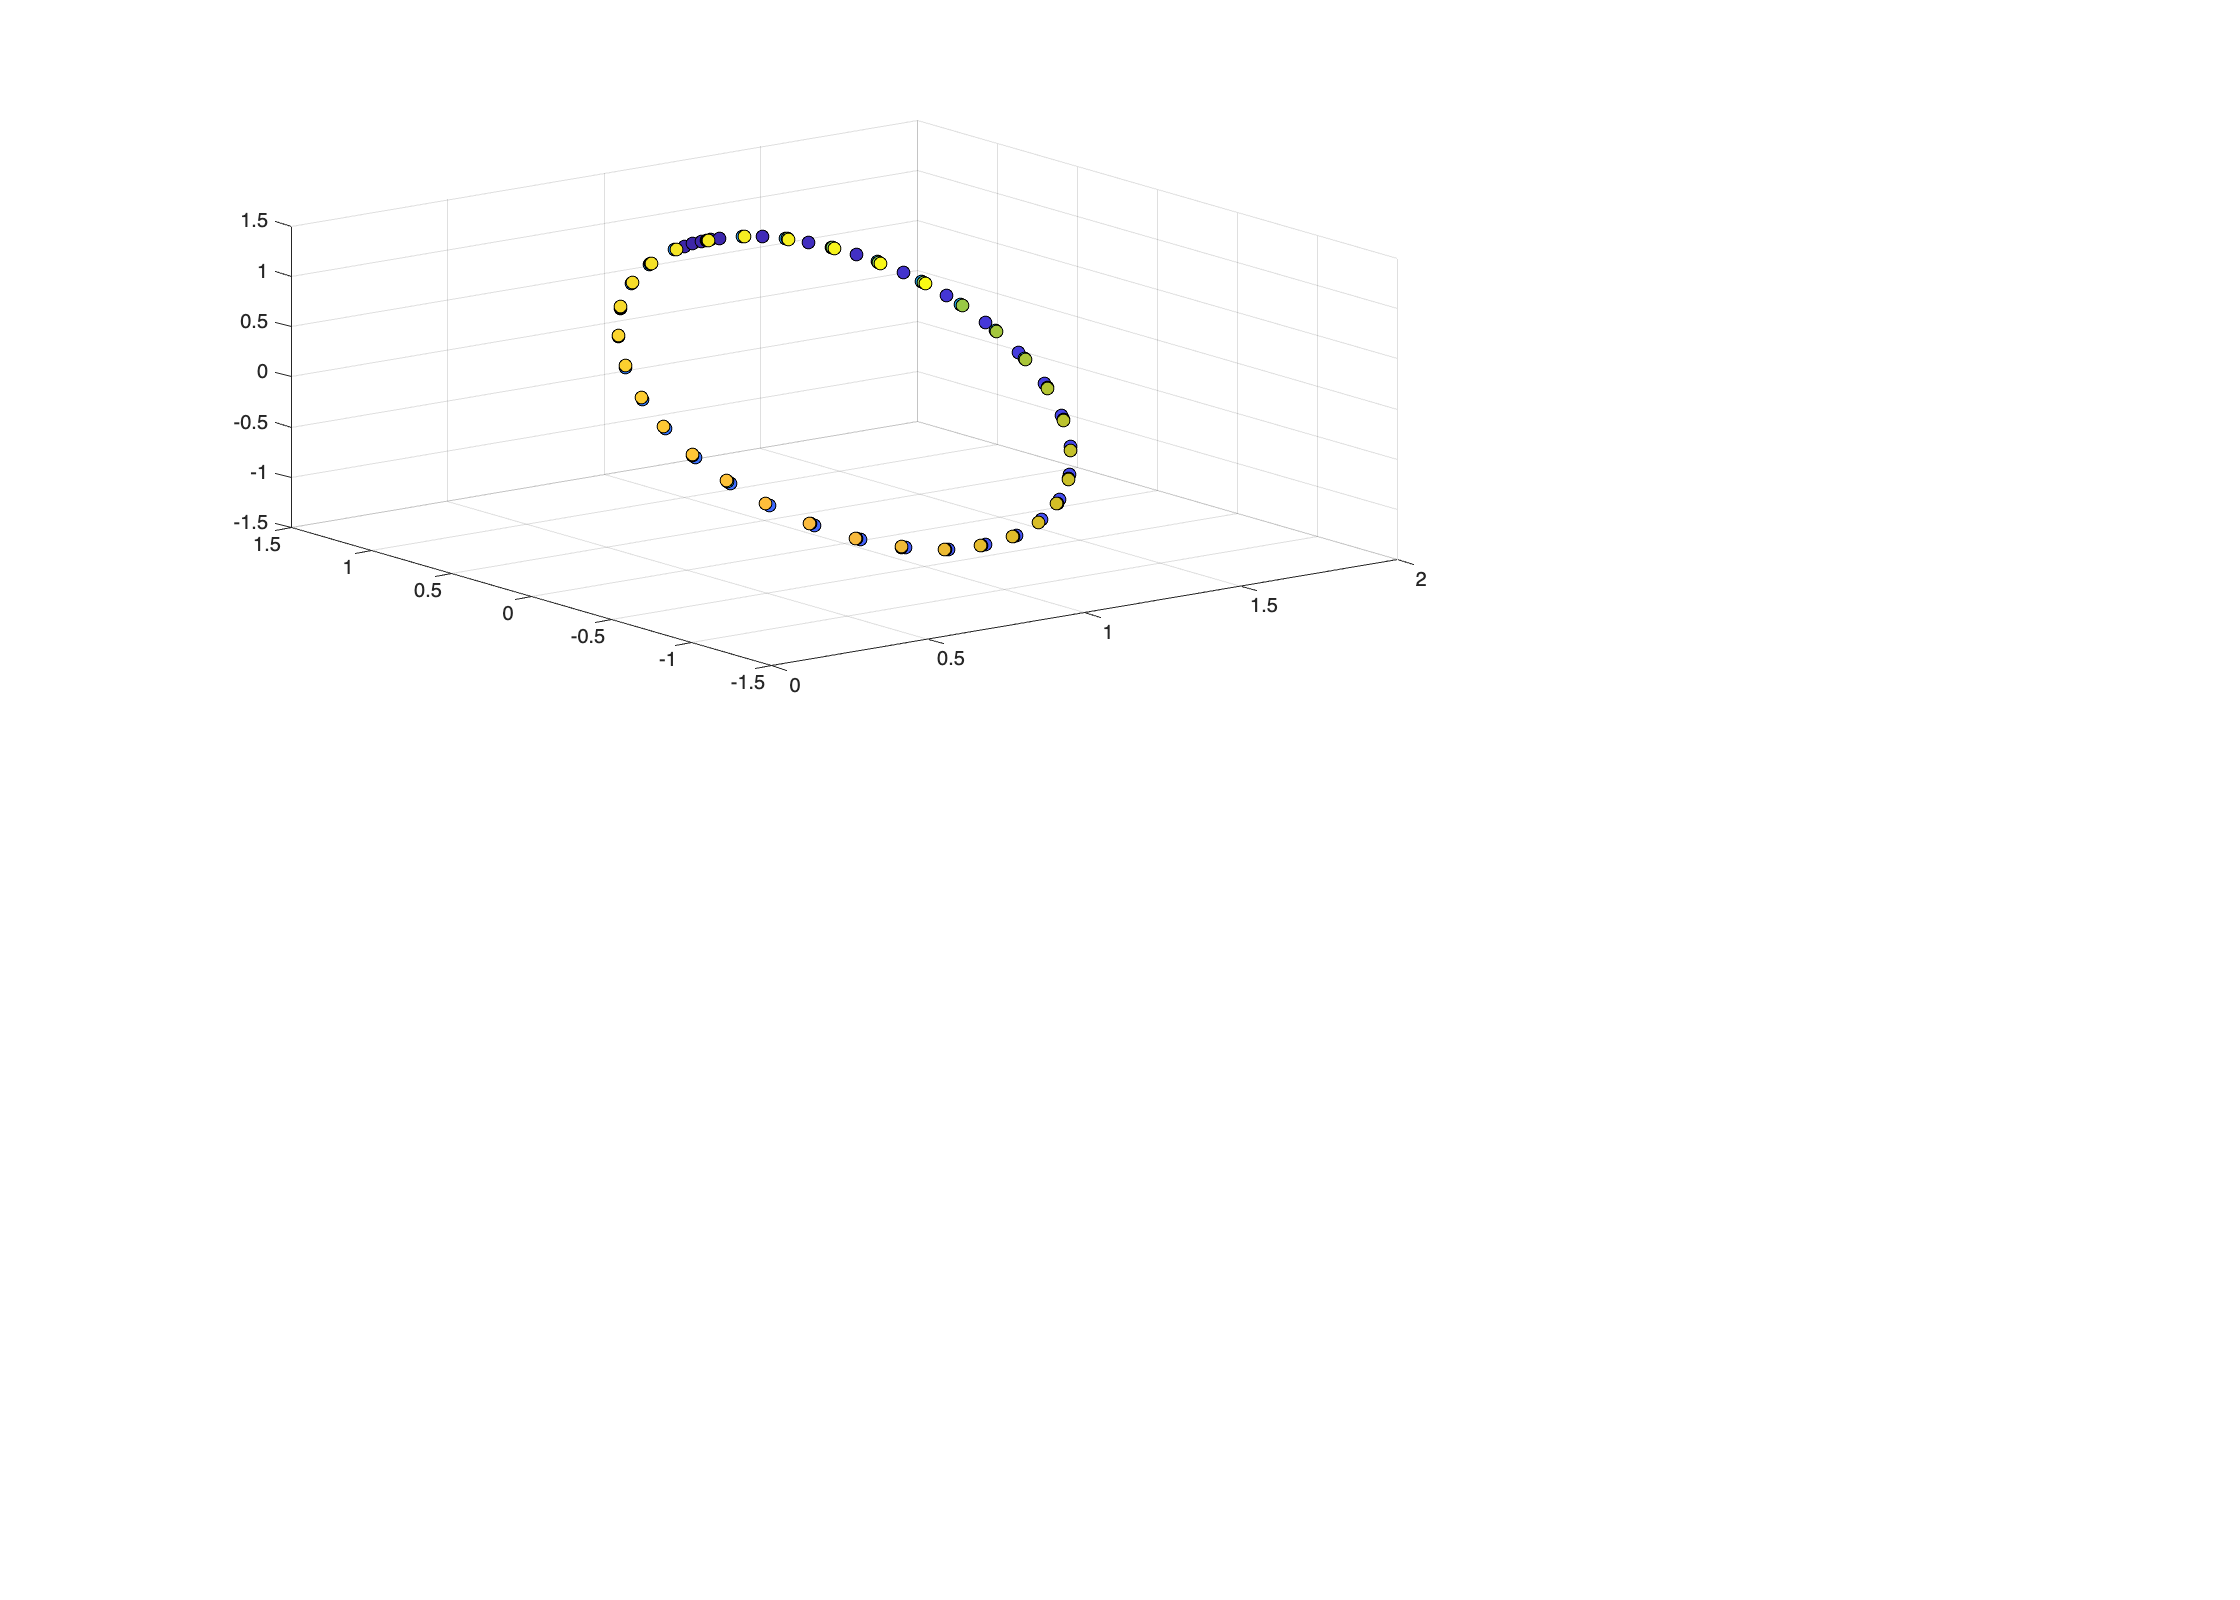


% Parámetros del caso degenerado
alpha = 0;
beta = 0;
delta = 0;

% Condición inicial específica
initial_condition = [1, 1, 1];

%% RESOLUCIÓN NUMÉRICA
% Definir el sistema de ecuaciones
lorenz_system = @(t, X) [
    alpha * (X(2) - X(1));      % x' = 0
    -X(1)*X(3) + delta * X(2);  % y' = -xz
    X(1)*X(2) - beta * X(3)     % z' = xy
];

% Tiempo de simulación
t_span = [0, 20];
[t, X] = ode45(lorenz_system, t_span, initial_condition);

%% GRÁFICA PRINCIPAL CON COLORBAR TEMPORAL
figure('Position', [100, 100, 1400, 1000]);

% Subplot 1: Trayectoria 3D con colorbar temporal
subplot(2, 3, [1, 2]);
% Gráfica con colores según el tiempo
scatter3(X(:,1), X(:,2), X(:,3), 40, t, 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 0.5);
hold on;

% Línea que conecta los puntos para mejor visualización
plot3(X(:,1), X(:,2), X(:,3), 'k-', 'LineWidth', 0.5, 'Alpha', 0.3);

Error using plot3
Unrecognized property Alpha for class Line.

% Puntos inicial y final
plot3(X(1,1), X(1,2), X(1,3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k');
plot3(X(end,1), X(end,2), X(end,3), 'gs', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k');

grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title('Trayectoria 3D - Color indica Tiempo', 'FontSize', 12);
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo';
c.Label.FontSize = 11;
legend('Trayectoria (color=tiempo)', 'Línea guía', 'Inicio (t=0)', 'Final', 'Location', 'best');
view(45, 30);

%% GRÁFICA 2: COMPONENTES vs TIEMPO CON COLORES
% Subplot 2: Componente x
subplot(2, 3, 3);
plot(t, X(:,1), 'r-', 'LineWidth', 3);
grid on;
xlabel('Tiempo'); ylabel('x(t)');
title('Componente x vs Tiempo');
legend(sprintf('x(t) = %.2f (constante)', initial_condition(1)), 'Location', 'best');

% Subplot 3: Componente y con color según tiempo
subplot(2, 3, 4);
scatter(t, X(:,2), 40, t, 'filled', 'MarkerEdgeColor', 'k');
hold on;
plot(t, X(:,2), 'k-', 'LineWidth', 0.5, 'Alpha', 0.3);
grid on;
xlabel('Tiempo'); ylabel('y(t)');
title('Componente y vs Tiempo (color=tiempo)');
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo';

% Subplot 4: Componente z con color según tiempo
subplot(2, 3, 5);
scatter(t, X(:,3), 40, t, 'filled', 'MarkerEdgeColor', 'k');
hold on;
plot(t, X(:,3), 'k-', 'LineWidth', 0.5, 'Alpha', 0.3);
grid on;
xlabel('Tiempo'); ylabel('z(t)');
title('Componente z vs Tiempo (color=tiempo)');
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo';

% Subplot 5: Plano de fases y-z con color según tiempo
subplot(2, 3, 6);
scatter(X(:,2), X(:,3), 40, t, 'filled', 'MarkerEdgeColor', 'k');
hold on;
plot(X(:,2), X(:,3), 'k-', 'LineWidth', 0.5, 'Alpha', 0.3);
plot(X(1,2), X(1,3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k');
plot(X(end,2), X(end,3), 'gs', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k');
grid on;
xlabel('y'); ylabel('z');
title('Plano de Fases y-z (color=tiempo)');
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo';
legend('Trayectoria', 'Línea guía', 'Inicio', 'Final', 'Location', 'best');

sgtitle('Sistema Degenerado: α=β=δ=0 con Condición Inicial (1,1,1) - Evolución Temporal', 'FontSize', 14, 'FontWeight', 'bold');

%% GRÁFICA 3: ANÁLISIS TEMPORAL DETALLADO CON COLORES
figure('Position', [100, 100, 1200, 800]);

% Subplot 1: Trayectoria 3D con colorbar mejorado
subplot(2, 2, 1);
% Crear superficie de colores para mejor visualización temporal
patch([X(:,1); NaN], [X(:,2); NaN], [X(:,3); NaN], [t; NaN], ...
      'EdgeColor', 'interp', 'LineWidth', 4, 'FaceColor', 'none');
hold on;
plot3(X(1,1), X(1,2), X(1,3), 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k', 'LineWidth', 2);
plot3(X(end,1), X(end,2), X(end,3), 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k', 'LineWidth', 2);
grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title('Trayectoria 3D - Evolución Temporal', 'FontSize', 12);
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo (s)';
c.Label.FontSize = 11;
view(45, 30);

% Subplot 2: Plano de fases y-z con línea de tiempo gruesa
subplot(2, 2, 2);
% Usar patch para línea con color interpolado
patch([X(:,2); NaN], [X(:,3); NaN], [t; NaN], ...
      'EdgeColor', 'interp', 'LineWidth', 6, 'FaceColor', 'none');
hold on;
plot(X(1,2), X(1,3), 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'k', 'LineWidth', 2);
plot(X(end,2), X(end,3), 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k', 'LineWidth', 2);
grid on;
xlabel('y'); ylabel('z');
title('Plano de Fases y-z - Evolución Temporal', 'FontSize', 12);
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo (s)';
c.Label.FontSize = 11;

% Subplot 3: Componentes y,z vs tiempo con colores
subplot(2, 2, 3);
% Gráfica de y(t) con colores
yyaxis left;
patch([t; NaN], [X(:,2); NaN], [t; NaN], ...
      'EdgeColor', 'interp', 'LineWidth', 4, 'FaceColor', 'none');
ylabel('y(t)');
ylim([min(X(:,2))-0.1, max(X(:,2))+0.1]);

% Gráfica de z(t) con colores
yyaxis right;
patch([t; NaN], [X(:,3); NaN], [t; NaN], ...
      'EdgeColor', 'interp', 'LineWidth', 4, 'FaceColor', 'none');
ylabel('z(t)');
ylim([min(X(:,3))-0.1, max(X(:,3))+0.1]);

xlabel('Tiempo (s)');
title('Componentes y(t) y z(t) - Evolución Temporal', 'FontSize', 12);
grid on;
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo (s)';

% Subplot 4: Velocidad en el plano y-z vs tiempo
subplot(2, 2, 4);
% Calcular velocidad aproximada
dt = diff(t);
dy_dt = diff(X(:,2)) ./ dt;
dz_dt = diff(X(:,3)) ./ dt;
speed = sqrt(dy_dt.^2 + dz_dt.^2);
t_mid = (t(1:end-1) + t(2:end)) / 2;

scatter(t_mid, speed, 50, t_mid, 'filled', 'MarkerEdgeColor', 'k');
hold on;
plot(t_mid, speed, 'k-', 'LineWidth', 1, 'Alpha', 0.3);
grid on;
xlabel('Tiempo (s)');
ylabel('Velocidad en plano y-z');
title('Velocidad vs Tiempo', 'FontSize', 12);
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo (s)';

sgtitle('Análisis Temporal Detallado - Sistema Degenerado α=β=δ=0', 'FontSize', 14, 'FontWeight', 'bold');

%% GRÁFICA 4: EVOLUCIÓN TEMPORAL CON PUNTOS DISCRETOS
figure('Position', [100, 100, 1000, 800]);

% Seleccionar puntos equiespaciados en el tiempo para mejor visualización
n_points = min(50, length(t));  % Máximo 50 puntos para claridad
indices = round(linspace(1, length(t), n_points));
t_selected = t(indices);
X_selected = X(indices, :);

% Crear mapa de colores personalizado
custom_colormap = jet(n_points);

% Gráfica principal
subplot(2, 2, [1, 2]);
for i = 1:length(indices)-1
    idx = indices(i);
    color_idx = round((i-1) * (length(custom_colormap)-1) / (length(indices)-2)) + 1;
    
    % Línea entre puntos consecutivos
    plot3(X(idx:idx+1,1), X(idx:idx+1,2), X(idx:idx+1,3), ...
          'Color', custom_colormap(color_idx,:), 'LineWidth', 3);
    hold on;
    
    % Puntos discretos
    scatter3(X_selected(i,1), X_selected(i,2), X_selected(i,3), ...
             80, custom_colormap(color_idx,:), 'filled', 'MarkerEdgeColor', 'k');
end

% Punto final
scatter3(X_selected(end,1), X_selected(end,2), X_selected(end,3), ...
         100, custom_colormap(end,:), 'filled', 'MarkerEdgeColor', 'k', 'Marker', 's');

grid on;
xlabel('x'); ylabel('y'); zlabel('z');
title('Evolución Temporal - Puntos Discretos', 'FontSize', 12);
view(45, 30);

% Crear colorbar personalizado
c = colorbar;
colormap(custom_colormap);
c.Ticks = linspace(0, 1, 6);
c.TickLabels = arrayfun(@(x) sprintf('%.1f', x), linspace(t(1), t(end), 6), 'UniformOutput', false);
c.Label.String = 'Tiempo (s)';

% Gráfica del plano y-z con puntos temporales
subplot(2, 2, 3);
for i = 1:length(indices)-1
    color_idx = round((i-1) * (length(custom_colormap)-1) / (length(indices)-2)) + 1;
    
    plot(X_selected(i:i+1,2), X_selected(i:i+1,3), ...
         'Color', custom_colormap(color_idx,:), 'LineWidth', 3);
    hold on;
    
    scatter(X_selected(i,2), X_selected(i,3), 60, custom_colormap(color_idx,:), 'filled', 'MarkerEdgeColor', 'k');
end
scatter(X_selected(end,2), X_selected(end,3), 80, custom_colormap(end,:), 'filled', 'MarkerEdgeColor', 'k', 'Marker', 's');
grid on;
xlabel('y'); ylabel('z');
title('Plano y-z - Puntos Temporales');

% Gráfica del tiempo vs índice de punto
subplot(2, 2, 4);
scatter(1:length(indices), t_selected, 80, t_selected, 'filled', 'MarkerEdgeColor', 'k');
grid on;
xlabel('Índice del Punto');
ylabel('Tiempo (s)');
title('Distribución Temporal de Puntos');
colorbar;
colormap(jet);
c = colorbar;
c.Label.String = 'Tiempo (s)';

sgtitle('Visualización con Puntos Discretos en el Tiempo', 'FontSize', 14, 'FontWeight', 'bold');

%% INFORMACIÓN NUMÉRICA
fprintf('\n=== INFORMACIÓN TEMPORAL ===\n');
fprintf('Tiempo total de simulación: %.1f s\n', t(end));
fprintf('Número de puntos temporales: %d\n', length(t));
fprintf('Condición inicial (t=0): (%.1f, %.1f, %.1f)\n', initial_condition);
fprintf('Condición final (t=%.1f): (%.4f, %.4f, %.4f)\n', t(end), X(end,1), X(end,2), X(end,3));

% Calcular período aproximado si hay oscilaciones
if initial_condition(1) ~= 0
    % Encontrar cruces por cero de y
    zero_crossings = find(diff(sign(X(:,2))) ~= 0);
    if length(zero_crossings) >= 2
        period_estimate = 2 * (t(zero_crossings(2)) - t(zero_crossings(1)));
        fprintf('Período estimado de oscilación: %.4f s\n', period_estimate);
        fprintf('Frecuencia estimada: %.4f Hz\n', 1/period_estimate);
    end
end

fprintf('\nLa escala de colores (colorbar) muestra la evolución temporal:\n');
fprintf('- Azul: tiempos iniciales (t ≈ 0)\n');
fprintf('- Verde/Amarillo: tiempos intermedios\n');
fprintf('- Rojo: tiempos finales (t ≈ %.1f)\n', t(end));




%% ANÁLISIS DEL ATRACTOR DE LÜ - REPRESENTACIÓN GRÁFICA DE TODOS LOS CASOS
% Sistema:
% x' = α(y - x)
% y' = -xz + δy  
% z' = xy - βz

clear; clc; close all;

%% PARÁMETROS Y CONFIGURACIÓN
% Definiremos diferentes conjuntos de parámetros para cada caso
cases = {
    'Caso 1: α≠0, β≠0, δ≠0', [36, 3, 20], [0.1, 0.3, -0.6], [0, 50];
    'Caso 2: α=β=δ=0', [0, 0, 0], [1, 1, 1], [0, 20];
    'Caso 3: α=δ=0, β≠0', [0, 3, 0], [1, 0.5, 0], [0, 20];
    'Caso 4: α=0, δ≠0', [0, 3, 20], [0.1, 0.1, 0.1], [0, 30];
    'Caso 5: α≠0, β=0', [36, 0, 20], [0.1, 0.1, 0.1], [0, 5];
    'Caso 6: α≠0, β≠0', [36, 3, 20], [0.1, 0.3, -0.6], [0, 50]
};

%% FUNCIÓN PARA RESOLVER Y GRAFICAR CADA CASO
function plot_case(case_name, params, initial_cond, t_span, case_num)
    alpha_val = params(1);
    beta_val = params(2);
    delta_val = params(3);
    
    % Definir el sistema de ecuaciones
    lorenz_system = @(t, X) [
        alpha_val * (X(2) - X(1));
        -X(1)*X(3) + delta_val * X(2);
        X(1)*X(2) - beta_val * X(3)
    ];
    
    % Múltiples condiciones iniciales para ver comportamiento
    initial_conditions_set = [
        initial_cond;
        initial_cond .* [1.5, 0.8, 1.2];
        initial_cond .* [0.5, 1.5, 0.8];
        initial_cond .* [0.8, 0.5, 1.5]
    ];
    
    figure('Position', [100, 100, 1400, 1000]);
    
    % Colores para diferentes condiciones iniciales
    colors = ['r', 'g', 'b', 'm'];
    markers = ['o', 's', '^', 'd'];
    
    % Arrays para almacenar todas las trayectorias
    all_trajectories = [];
    
    for i = 1:size(initial_conditions_set, 1)
        try
            % Resolver el sistema
            [t, X] = ode45(lorenz_system, t_span, initial_conditions_set(i, :));
            
            % Almacenar para análisis posterior
            all_trajectories(i).t = t;
            all_trajectories(i).X = X;
            all_trajectories(i).color = colors(i);
            all_trajectories(i).marker = markers(i);
            
        catch ME
            fprintf('Advertencia: No se pudo resolver %s para condición inicial %d\n', case_name, i);
            fprintf('Error: %s\n', ME.message);
        end
    end
    
    %% GRÁFICA 1: TRAYECTORIAS 3D
    subplot(2, 3, [1, 2]);
    for i = 1:length(all_trajectories)
        if ~isempty(all_trajectories(i).X)
            X = all_trajectories(i).X;
            % Gráfica con color según tiempo
            scatter3(X(:,1), X(:,2), X(:,3), 30, all_trajectories(i).t, 'filled', ...
                    'MarkerEdgeColor', all_trajectories(i).color);
            hold on;
            % Línea de conexión (sin propiedad Alpha)
            plot3(X(:,1), X(:,2), X(:,3), 'k-', 'LineWidth', 0.5, 'Color', [0.5 0.5 0.5]);
            % Puntos inicial y final
            plot3(X(1,1), X(1,2), X(1,3), [all_trajectories(i).color all_trajectories(i).marker], ...
                  'MarkerSize', 8, 'MarkerFaceColor', all_trajectories(i).color);
            plot3(X(end,1), X(end,2), X(end,3), [all_trajectories(i).color all_trajectories(i).marker], ...
                  'MarkerSize', 8, 'MarkerFaceColor', all_trajectories(i).color);
        end
    end
    
    grid on;
    xlabel('x'); ylabel('y'); zlabel('z');
    title(sprintf('%s - Trayectorias 3D', case_name), 'FontSize', 12, 'FontWeight', 'bold');
    colorbar;
    colormap(jet);
    c = colorbar;
    c.Label.String = 'Tiempo';
    view(45, 30);
    
    %% GRÁFICA 2: COMPONENTES vs TIEMPO
    subplot(2, 3, 3);
    for i = 1:length(all_trajectories)
        if ~isempty(all_trajectories(i).X)
            plot(all_trajectories(i).t, all_trajectories(i).X(:,1), ...
                 [colors(i) '-'], 'LineWidth', 2);
            hold on;
        end
    end
    grid on;
    xlabel('Tiempo'); ylabel('x(t)');
    title('Componente x vs Tiempo');
    legend('Cond. 1', 'Cond. 2', 'Cond. 3', 'Cond. 4', 'Location', 'best');
    
    %% GRÁFICA 3: COMPONENTE Y
    subplot(2, 3, 4);
    for i = 1:length(all_trajectories)
        if ~isempty(all_trajectories(i).X)
            plot(all_trajectories(i).t, all_trajectories(i).X(:,2), ...
                 [colors(i) '-'], 'LineWidth', 2);
            hold on;
        end
    end
    grid on;
    xlabel('Tiempo'); ylabel('y(t)');
    title('Componente y vs Tiempo');
    
    %% GRÁFICA 4: COMPONENTE Z
    subplot(2, 3, 5);
    for i = 1:length(all_trajectories)
        if ~isempty(all_trajectories(i).X)
            plot(all_trajectories(i).t, all_trajectories(i).X(:,3), ...
                 [colors(i) '-'], 'LineWidth', 2);
            hold on;
        end
    end
    grid on;
    xlabel('Tiempo'); ylabel('z(t)');
    title('Componente z vs Tiempo');
    
    %% GRÁFICA 5: PLANO DE FASES Y-Z
    subplot(2, 3, 6);
    for i = 1:length(all_trajectories)
        if ~isempty(all_trajectories(i).X)
            X = all_trajectories(i).X;
            scatter(X(:,2), X(:,3), 30, all_trajectories(i).t, 'filled', ...
                   'MarkerEdgeColor', colors(i));
            hold on;
            plot(X(1,2), X(1,3), [colors(i) markers(i)], 'MarkerSize', 10, ...
                 'MarkerFaceColor', colors(i));
            plot(X(end,2), X(end,3), [colors(i) markers(i)], 'MarkerSize', 10, ...
                 'MarkerFaceColor', colors(i));
        end
    end
    grid on;
    xlabel('y'); ylabel('z');
    title('Plano de Fases y-z');
    colorbar;
    colormap(jet);
    
    %% INFORMACIÓN DEL CASO
    fprintf('\n=== %s ===\n', case_name);
    fprintf('Parámetros: α=%.1f, β=%.1f, δ=%.1f\n', alpha_val, beta_val, delta_val);
    fprintf('Condición inicial principal: (%.1f, %.1f, %.1f)\n', initial_cond);
    fprintf('Tiempo de simulación: [%.1f, %.1f]\n', t_span(1), t_span(2));
    
    % Análisis de estabilidad para el caso actual
    if case_num == 1
        fprintf('COMPORTAMIENTO: Caótico (atractor de Lü)\n');
    elseif case_num == 2
        fprintf('COMPORTAMIENTO: Degenerado - Oscilaciones armónicas\n');
        fprintf('x constante, sistema se reduce a oscilador en y-z\n');
    elseif case_num == 3
        fprintf('COMPORTAMIENTO: Degenerado - Depende de x₀\n');
        fprintf('Si x₀=0: z decae exponencialmente\n');
        fprintf('Si x₀≠0: Oscilaciones amortiguadas\n');
    elseif case_num == 4
        fprintf('COMPORTAMIENTO: Inestable para δ>0\n');
    elseif case_num == 5
        fprintf('COMPORTAMIENTO: Singular - Potencial crecimiento ilimitado\n');
        fprintf('Sin disipación en z (β=0)\n');
    elseif case_num == 6
        fprintf('COMPORTAMIENTO: Inestable (atractor caótico)\n');
    end
    
    sgtitle(sprintf('Análisis Completo - %s', case_name), 'FontSize', 14, 'FontWeight', 'bold');
end

%% EJECUTAR ANÁLISIS PARA TODOS LOS CASOS
fprintf('=== ANÁLISIS COMPLETO DE TODOS LOS CASOS ===\n');

for i = 1:size(cases, 1)
    case_name = cases{i, 1};
    params = cases{i, 2};
    initial_cond = cases{i, 3};
    t_span = cases{i, 4};
    
    fprintf('\nProcesando %s...\n', case_name);
    plot_case(case_name, params, initial_cond, t_span, i);
    
    % Pausa breve entre figuras
    pause(1);
end

%% ANÁLISIS COMPARATIVO ENTRE CASOS
fprintf('\n=== ANÁLISIS COMPARATIVO ===\n');

% Crear figura comparativa
figure('Position', [100, 100, 1500, 1000]);

for i = 1:6
    case_name = cases{i, 1};
    params = cases{i, 2};
    initial_cond = cases{i, 3};
    t_span = cases{i, 4};
    
    alpha_val = params(1);
    beta_val = params(2);
    delta_val = params(3);
    
    % Resolver para condición inicial principal
    lorenz_system = @(t, X) [
        alpha_val * (X(2) - X(1));
        -X(1)*X(3) + delta_val * X(2);
        X(1)*X(2) - beta_val * X(3)
    ];
    
    try
        [t, X] = ode45(lorenz_system, t_span, initial_cond);
        
        subplot(2, 3, i);
        
        % Gráfica 3D de la trayectoria principal
        plot3(X(:,1), X(:,2), X(:,3), 'b-', 'LineWidth', 2);
        hold on;
        plot3(X(1,1), X(1,2), X(1,3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
        plot3(X(end,1), X(end,2), X(end,3), 'gs', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
        
        grid on;
        xlabel('x'); ylabel('y'); zlabel('z');
        title(sprintf('%s\nα=%.1f, β=%.1f, δ=%.1f', ...
              strrep(case_name, ':', '\n'), alpha_val, beta_val, delta_val), ...
              'FontSize', 10);
        view(45, 30);
        
    catch ME
        fprintf('Error en caso %d: %s\n', i, ME.message);
    end
end

sgtitle('Comparativa de Todos los Casos - Trayectorias 3D Principales', ...
        'FontSize', 16, 'FontWeight', 'bold');

%% GRÁFICA ESPECIAL: COMPORTAMIENTO TEMPORAL COMPARATIVO
figure('Position', [100, 100, 1400, 900]);

% Colores para diferentes casos
case_colors = ['r', 'g', 'b', 'm', 'c', 'k'];
case_styles = {'-', '--', ':', '-.', '--', '-'};

for i = 1:6
    case_name = cases{i, 1};
    params = cases{i, 2};
    initial_cond = cases{i, 3};
    t_span = cases{i, 4};
    
    alpha_val = params(1);
    beta_val = params(2);
    delta_val = params(3);
    
    % Resolver sistema
    lorenz_system = @(t, X) [
        alpha_val * (X(2) - X(1));
        -X(1)*X(3) + delta_val * X(2);
        X(1)*X(2) - beta_val * X(3)
    ];
    
    try
        [t, X] = ode45(lorenz_system, t_span, initial_cond);
        
        % Normalizar tiempo para comparación
        t_norm = t / max(t);
        
        subplot(2, 3, 1);
        plot(t_norm, X(:,1), [case_colors(i) case_styles{i}], 'LineWidth', 2);
        hold on;
        ylabel('x(t)');
        title('Comparativa - Componente x');
        
        subplot(2, 3, 2);
        plot(t_norm, X(:,2), [case_colors(i) case_styles{i}], 'LineWidth', 2);
        hold on;
        ylabel('y(t)');
        title('Comparativa - Componente y');
        
        subplot(2, 3, 3);
        plot(t_norm, X(:,3), [case_colors(i) case_styles{i}], 'LineWidth', 2);
        hold on;
        ylabel('z(t)');
        title('Comparativa - Componente z');
        
        % Gráficas de planos de fase
        subplot(2, 3, 4);
        plot(X(:,1), X(:,2), [case_colors(i) case_styles{i}], 'LineWidth', 1.5);
        hold on;
        xlabel('x'); ylabel('y');
        title('Plano x-y');
        
        subplot(2, 3, 5);
        plot(X(:,2), X(:,3), [case_colors(i) case_styles{i}], 'LineWidth', 1.5);
        hold on;
        xlabel('y'); ylabel('z');
        title('Plano y-z');
        
        subplot(2, 3, 6);
        plot(X(:,1), X(:,3), [case_colors(i) case_styles{i}], 'LineWidth', 1.5);
        hold on;
        xlabel('x'); ylabel('z');
        title('Plano x-z');
        
    catch ME
        fprintf('Error en gráfica comparativa caso %d: %s\n', i, ME.message);
    end
end

% Añadir leyendas
subplot(2, 3, 1);
legend(cases{1,1}, cases{2,1}, cases{3,1}, cases{4,1}, cases{5,1}, cases{6,1}, ...
       'Location', 'best', 'FontSize', 8);

sgtitle('Análisis Comparativo - Todos los Casos Degenerados', ...
        'FontSize', 16, 'FontWeight', 'bold');

%% VERSIÓN SIMPLIFICADA PARA CASOS PROBLEMÁTICOS
fprintf('\n=== VERSIÓN SIMPLIFICADA PARA CASOS ESPECIALES ===\n');

% Figura simplificada para casos que pueden fallar
figure('Position', [100, 100, 1200, 800]);

for i = 1:6
    case_name = cases{i, 1};
    params = cases{i, 2};
    initial_cond = cases{i, 3};
    t_span = cases{i, 4};
    
    alpha_val = params(1);
    beta_val = params(2);
    delta_val = params(3);
    
    % Resolver sistema
    lorenz_system = @(t, X) [
        alpha_val * (X(2) - X(1));
        -X(1)*X(3) + delta_val * X(2);
        X(1)*X(2) - beta_val * X(3)
    ];
    
    try
        [t, X] = ode45(lorenz_system, t_span, initial_cond);
        
        subplot(2, 3, i);
        
        % Gráfica simple y robusta
        plot3(X(:,1), X(:,2), X(:,3), 'b-', 'LineWidth', 2);
        hold on;
        plot3(X(1,1), X(1,2), X(1,3), 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
        plot3(X(end,1), X(end,2), X(end,3), 'gs', 'MarkerSize', 6, 'MarkerFaceColor', 'g');
        
        grid on;
        xlabel('x'); ylabel('y'); zlabel('z');
        title(sprintf('%s', strrep(case_name, ':', '\n')), 'FontSize', 10);
        view(45, 30);
        
        % Información en consola
        fprintf('Caso %d: %s - Puntos calculados: %d\n', i, case_name, length(t));
        
    catch ME
        fprintf('ERROR en caso %d (%s): %s\n', i, case_name, ME.message);
        
        subplot(2, 3, i);
        text(0.5, 0.5, sprintf('Error en simulación\n%s', case_name), ...
             'HorizontalAlignment', 'center', 'FontSize', 12);
        title(sprintf('Caso %d: Error', i));
        axis off;
    end
end

sgtitle('Análisis Simplificado - Todos los Casos', 'FontSize', 16, 'FontWeight', 'bold');

%% RESUMEN FINAL
fprintf('\n=== RESUMEN FINAL ===\n');
fprintf('Se han analizado los siguientes casos:\n');
for i = 1:6
    fprintf('%d. %s\n', i, cases{i,1});
end
fprintf('\nCada caso muestra comportamientos cualitativamente diferentes:\n');
fprintf('- Caso 1 y 6: Comportamiento caótico típico\n');
fprintf('- Caso 2: Sistema completamente degenerado (oscilaciones)\n');
fprintf('- Caso 3: Degenerado con amortiguamiento\n');
fprintf('- Caso 4: Inestable con crecimiento exponencial\n');
fprintf('- Caso 5: Sistema singular (potencial divergencia)\n');
